# INPUT

[audio_data, Fs] = audioread("test_audio_file.wav");
% [noise_data, Fs2] = audioread("test_noise_file.wav");
% sound(audio_data, Fs, 8);

## Audio player

sound(audio_data, Fs, 8);
dt = 1/Fs;
time =linspace(0,length(audio_data)*dt,length(audio_data));
len_time = length(audio_data) / Fs

len_time = 4

data_range = length(audio_data);

## Plot for amplitude vs Time

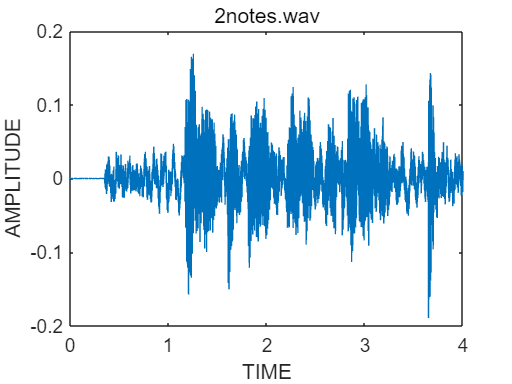

figure(1)
plot(time,audio_data);
xlabel("TIME");
ylabel("AMPLITUDE");
title("2notes.wav");
hold on

% plot(time,noise_data);
% hold off

## Power and Normarlized_Power

% 
data_period = 0.1;
period_number = len_time / data_period;
step_number = data_range / period_number;
for i = 1:period_number
    range_left = (i-1)*step_number+1;
    range_right = i*step_number;
    power_to_test = pow(range_left,range_right,audio_data)/0.1
    if power_to_test <10
        for e = range_left:range_right
            audio_data(e) = 0;
        end
    end
end

power_to_test = 9.4064e-07

power_to_test = 9.5554e-07

power_to_test = 9.3598e-07

power_to_test = 0.2768

power_to_test = 0.9272

power_to_test = 0.4141

power_to_test = 0.3970

power_to_test = 0.6953

power_to_test = 0.9525

power_to_test = 1.8120

power_to_test = 1.3115

power_to_test = 4.6619

power_to_test = 10.6004

power_to_test = 5.1122

power_to_test = 5.2834

power_to_test = 1.5984

power_to_test = 9.5808

power_to_test = 1.9954

power_to_test = 8.3843

power_to_test = 5.6300

power_to_test = 2.1345

power_to_test = 1.0006

power_to_test = 5.5417

power_to_test = 4.6203

power_to_test = 4.4008

power_to_test = 1.2513

power_to_test = 4.3307

power_to_test = 1.7994

power_to_test = 8.9310

power_to_test = 8.5500

power_to_test = 6.1657

power_to_test = 2.4051

power_to_test = 1.0755

power_to_test = 1.1619

power_to_test = 1.8504

power_to_test = 1.1336

power_to_test = 10.8691

power_to_test = 1.3874

power_to_test = 0.9936

power_to_test = 0.7861

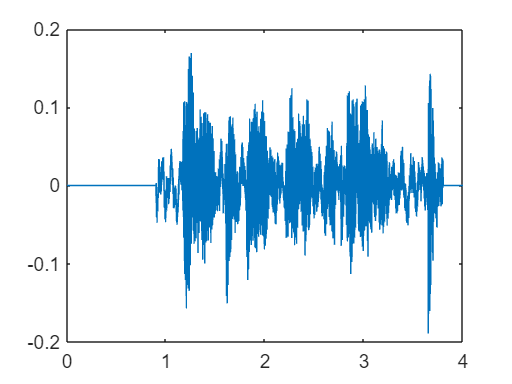

sound(audio_data, Fs, 8);
figure(2)
plot(time,audio_data)

length(audio_data)

ans = 177200

new_length = length(audio_data)/2;
audio_data_half = audio_data(1:new_length);

function [pow] = pow(timeLeft,timeRight,amp)
    pow=0;
    for i = timeLeft:timeRight
        pow = pow + amp(i)^2;
    end
end
